# COVID-19 Detection Using X-Rays

by Joshua Rothe

## Image pre-processing, K-Means

K = 5;  % for K-means

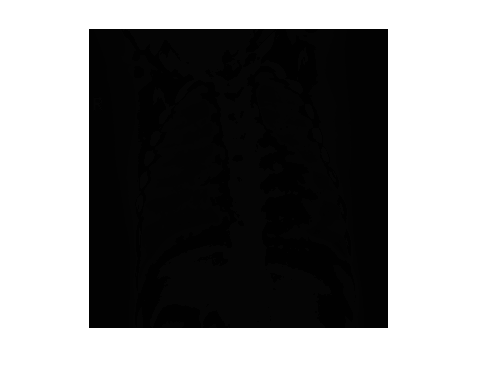

% Class - normal images
num_images = 500;
normal_img = zeros((299*299),num_images);   % Initialize empty array
for i = 1:num_images
    filename = sprintf('./data/normal/Normal-%i.png', i);
    img = (imread(filename));
    % Perform K-means for the image (comment out below if not using)
    img = imsegkmeans(img,K);
    normal_img(:,i) = double(reshape(img,[],1));    % reshapes image as column vector
end                                                 % and adds it to normal_img
labels(1:num_images,1) = "normal";
imshow(img);

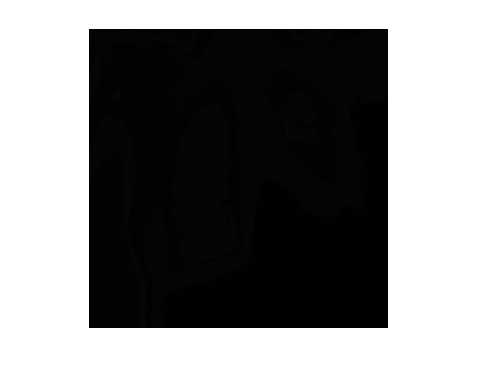

% Class - COVID
num_images2 = 500;
cov_img = zeros((299*299),num_images2);  % Initialize empty array
for i = 1:num_images2
    filename = sprintf('./data/COVID/COVID-%i.png', i);
    img = (imread(filename));
    % Perform K-means for the image (comment out below if not using)
    img = imsegkmeans(img,K);
    cov_img(:,i) = double(reshape(img,[],1));       % reshapes image as column vector
end                                                 % and adds it to cov_img
labels(num_images+1:num_images2+num_images,1) = "COVID";
imshow(img);

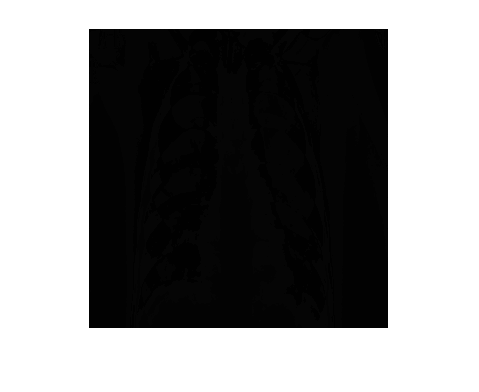

% Class - Viral Pneumonia images
num_images3 = 500;
pnu_img = zeros((299*299),num_images3);   % Initialize empty array
for i = 1:num_images3
    filename = sprintf('./data/Viral Pneumonia/Viral Pneumonia-%i.png', i);
    img = (imread(filename));
    % Perform K-means for the image (comment out below if not using)
    img = imsegkmeans(img,K);
    pnu_img(:,i) = double(reshape(img,[],1));   % reshapes image as column vector
end                                             % and adds it to pnu_img
labels(num_images+num_images2+1:num_images+num_images2+num_images3,1) = "viral pneumonia";                  
imshow(img);

% Combine images and labels
train_images = [normal_img, cov_img, pnu_img];
train_labels = labels;

## Apply PCA

%% Train and find the PCA dimensions of the training data
% First reduce the training data to a computationally manageable size
% (note: in this instance, size is unchanged, but may adjust as needed)
train_size = num_images + num_images2 + num_images3;
% Reduced variables are for if we reduce the number if pics taken from dataset.
train_images_reduced = train_images(:,[1:train_size]);
train_labels_reduced = train_labels([1:train_size],:);
% Normalize the data, will be calling it X for simplicity
X = train_images_reduced;
Xmean = mean(X);    % mean of X
Xnorm = X - Xmean;  % normalized
% Calculate covariance matrix
covar_matrix = (Xnorm' * Xnorm) / (train_size - 1);
% Calculate Eigenvectors and Eigenvalues of Covariance Matrix
[Xeivec, Xeival] = eig(covar_matrix);
% Now project the dataset
proj_train = Xnorm * Xeivec;
% Back into larger data format
Xnormk_train = proj_train * Xeivec';

## Create Models

% Create a model with standard params
% Mdl = fitcecoc(Xnormk_train',train_labels_reduced');
% Note: This model performs poorly. More than 50% error when 
% tested using predict().
% error = resubLoss(Mdl)  % resubloss error

% Obtain better model performance with parameters
t = templateSVM('Standardize',true);
Mdl2 = fitcecoc(Xnormk_train',train_labels_reduced',...
    'Learners',t,'ClassNames',{'normal','COVID','viral pneumonia'});
% error = resubLoss(Mdl2)  % resubloss error

% Cross validate the model
% options = statset('UseParallel',true);
% CVMdl2 = crossval(Mdl2,'Options',options);
% kFoldError2 = kfoldLoss(CVMdl2) % kfoldloss error from cross validated model

If error is low but kFoldError is high, the model is overfitted.

% Create model with optimized parameters
t = templateSVM('Standardize',true,'KernelScale', 290.69, ...
    'BoxConstraint', 28.161);
Mdl3 = fitcecoc(Xnormk_train',train_labels_reduced',...
    'Learners',t,'Coding',"onevsone",'ClassNames',{'normal','COVID','viral pneumonia'});
% error = resubLoss(Mdl3)  % resubloss error

% Cross validate the model
% options = statset('UseParallel',true);
% CVMdl3 = crossval(Mdl3,'Options',options);
% kFoldError3 = kfoldLoss(CVMdl3) % kfoldloss error from cross validated model

## Test Models

% Return a vector of predicted values, should all be non-COVID.
% test data is 8001 - 8100
clear test_label_healthy2; clear test_data_healthy; 
clear test_label_healthy3; k = 1;
%test_data_healthy = zeros((299*299),(1000));   % Initialize empty array
for i = 7001:8000
    filename = sprintf('./data/normal/Normal-%i.png', i);
    img = (imread(filename));
    test_data_healthy(:,k) = double(reshape(img,[],1));    % reshapes image as column vector
    k = k + 1;  % increment k for matrix pos
end
[test_label_healthy2] = predict(Mdl2,test_data_healthy');
[test_label_healthy3] = predict(Mdl3,test_data_healthy');

% Return a vector of predicted values, should all be all COVID infections.
% test data is 2001 - 3000
clear test_label_covid2; clear test_data_covid; 
clear test_label_covid3; k = 1;
%test_data_covid = zeros((299*299),(1000));   % Initialize empty array
for i = 2001:3000
    filename = sprintf('./data/COVID/COVID-%i.png', i);
    img = (imread(filename));
    test_data_covid(:,k) = double(reshape(img,[],1));    % reshapes image as column vector
    k = k + 1;  % increment k for matrix pos
end
[test_label_covid2] = predict(Mdl2,test_data_covid');
[test_label_covid3] = predict(Mdl3,test_data_covid');

% Return a vector of predicted values, should all be all Viral Pneumonia.
% test data is only 100 images due to data size. 1001 - 1100
clear test_label_pnu2; clear test_data_pnu; 
clear test_label_pnu3; k = 1;
%test_data_pnu = zeros((299*299),(100));   % Initialize empty array
for i = 1001:1100
    filename = sprintf('./data/Viral Pneumonia/Viral Pneumonia-%i.png', i);
    img = (imread(filename));
    test_data_pnu(:,k) = double(reshape(img,[],1));    % reshapes image as column vector
    k = k + 1;  % increment k for matrix pos
end
[test_label_pnu2] = predict(Mdl2,test_data_pnu');
[test_label_pnu3] = predict(Mdl3,test_data_pnu');

### Mdl2 - Default Paramaters

Accuracy with both the Healthy and COVID datasets was observed to try and see if the model skewed towards false positives or false negatives.

#### Healthy Test

% Check performance by counting number of times correct value was reached
perf_healthy_temp2a = categorical(test_label_healthy2);
labels_perf2a = categories(perf_healthy_temp2a) % displays labels

labels_perf2a = 3×1 cell array
    {'COVID'          }
    {'normal'         }
    {'viral pneumonia'}


perf_healthy2a = countcats(perf_healthy_temp2a) % displays occurance per label

perf_healthy2a =    356
   623
    21


Mdl2 with no K-Means is 93.2% accurate at detecting healthy images.

#### COVID Test

% Check performance by counting number of times correct value was reached
perf_covid_temp2b = categorical(test_label_covid2);
labels_perf2b = categories(perf_covid_temp2b) % displays labels

labels_perf2b = 3×1 cell array
    {'COVID'          }
    {'normal'         }
    {'viral pneumonia'}


perf_covid2b = countcats(perf_covid_temp2b) % displays occurance per label

perf_covid2b =    257
   663
    80


Mdl2 with no K-Means is 22.4% accurate at detecting COVID infection. 73.1% of images were mistaken as healthy. Leans very heavy on false negatives.

#### Viral Pneumonia Test

% Check performance by counting number of times correct value was reached
perf_pnu_temp2c = categorical(test_label_pnu2);
labels_perf2c = categories(perf_pnu_temp2c) % displays labels

labels_perf2c = 3×1 cell array
    {'COVID'          }
    {'normal'         }
    {'viral pneumonia'}


perf_pnu2c = countcats(perf_pnu_temp2c) % displays occurance per label

perf_pnu2c =     19
    32
    49


Mdl2 with no K-Means is 73% accurate at detecting Viral Pneumonia infection. All others it mistook as healthy (again, false negatives).

### Mdl3 - Optimized Paramaters

Same as Mdl2 except with the optimized model. Results are greatly improved.

#### Healthy Test

% Check performance by counting number of times correct value was reached
perf_healthy_temp3a = categorical(test_label_healthy3);
labels_perf3a = categories(perf_healthy_temp3a) % displays labels

labels_perf3a = 3×1 cell array
    {'COVID'          }
    {'normal'         }
    {'viral pneumonia'}


perf_healthy3a = countcats(perf_healthy_temp3a) % displays occurance per label

perf_healthy3a =    356
   623
    21


Mdl3 with no K-Means is 98.7% accurate at detecting healthy images with the old numbers.

After optimising with new numbers, it was 96.7% accurate. 0.9% it thought was pneumonia, and 2.4% it labeled COVID.

#### COVID Test

% Check performance by counting number of times correct value was reached
perf_covid_temp3b = categorical(test_label_covid3);
labels_perf3b = categories(perf_covid_temp3b) % displays labels

labels_perf3b = 3×1 cell array
    {'COVID'          }
    {'normal'         }
    {'viral pneumonia'}


perf_covid3b = countcats(perf_covid_temp3b) % displays occurance per label

perf_covid3b =    257
   663
    80


Mdl3 with no K-Means is 2% accurate at detecting COVID infection with the old numbers.

Newer optimized numbers give us 10.7% COVID, and 81.5% healthy. 7.8% were falsely labeled as viral pneumonia.

#### Viral Pneumonia Test

% Check performance by counting number of times correct value was reached
perf_pnu_temp3c = categorical(test_label_pnu3);
labels_perf3c = categories(perf_pnu_temp3c) % displays labels

labels_perf3c = 3×1 cell array
    {'COVID'          }
    {'normal'         }
    {'viral pneumonia'}


perf_pnu3c = countcats(perf_pnu_temp3c) % displays occurance per label

perf_pnu3c =     19
    32
    49


Mdl3 with no K-Means is 3% accurate at detecting Viral Pneumonia infection with the old numbers.

Newer optimized numbers detect viral pneumonia with an 80% accuracy. The rest were declared healthy - no COVID false positives.